# Communicating Discoveries

Load the data and model

load Data/allCountyData allCountyData 
load countyMasks
load expGPRnew.mat

## Explore predictions and mask usage

Adjust mask usage survey data and see the effect of the prediction.

Enter the location and adjust the values.

county = "Suffolk"; 
state = "MA"; 
numDaysToPredict = 28;  

Select mask survey values. Either use the actual values or adjust sliders to see the effect on the predictions. Median values (from never to always) 0.0680    0.0730    0.1160    0.2040    0.4970

useActualMaskValues = true;
Never =     0.63;
Rarely =  0.7;
Sometimes = 0.2;
Frequently =0.2;
Always =0.3;

 

Use the function to make the predictions and display on a plot.

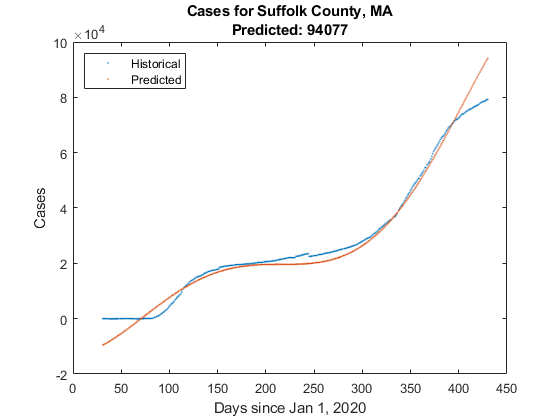

[predcases,thiscounty] = predictAndPlot(regressionGP,...
    allCountyData,county,state);
title(["Cases for "+county+" County, "+state,...
    "Predicted: "+string(floor(predcases(end)))])

% 
% mycounty = uscounties(uscounties.county == county & ...
%     uscounties.state == state,:);
% figure
% if useActualMaskValues  
%     mycounty = 
%     predData = predictCases(model,data,numdays,newmaskrtgs)
%     testData = predictCases(regressionGP,mycounty);
% else 
%     newmaskrtgs = [Never,Rarely,Sometimes,Frequently,Always];
%     testData = predictCases(regressionGP,mycounty,newmaskrtgs);
%     
% end
% figure
% predcases = testData.predcases;
% plot(a,testData.date,testData.cases,'.')
% hold on
% plot(a,tf,predcases,".")
% xline(a,datetime("now"),"--","Today","LabelVerticalAlignment","bottom")
% % hold off
% legend(a,"Historical","Predicted","Today","Location","northwest")
% title(a,["Cases for "+cty+" County, "+st,...
%     "Predicted: "+string(floor(predcases(end)))])


## Explore overall summary

Select to visualize.

% loc = "us";
% variable = "cases";
% timestep = "daily";
% plotType = "line";
% byPopulation = false;
% includeMasks = false;
% calcs = "total";
% topvals = 10;

## Compare locations

Select locations to compare (just create an app... labels are annoying

% % type in
% location1 = "Alabama";
% location2 = "Florida";
% location3 = "Massachusetts";
%  
% % idx = ismember()
% figure
% plot(usstates.date(usstates.state == location1),...
%     usstates.cases(usstates.state == location1))
% hold on
% plot(usstates.date(usstates.state == location2),...
%     usstates.cases(usstates.state == location2))
% plot(usstates.date(usstates.state == location3),...
%     usstates.cases(usstates.state == location3))
% hold off
% legend([location1,location2,location3],'Location',"best")


function [predcases,thiscounty] = predictAndPlot(regressionGP,allCountyData,cty,st)
idx = allCountyData.county == cty & allCountyData.abbrev == st;
thiscounty = timetable2table(allCountyData(idx,:));
thiscounty.dayvalue = thiscounty.date - datetime(2020,1,1);
thiscounty.dayvalue = days(thiscounty.dayvalue);
thiscounty.state = removecats(thiscounty.state);
thiscounty.county = removecats(thiscounty.county);
vars = ["dayvalue","cases","POPESTIMATE2019","LON","LAT",... 
    "NEVER","RARELY","SOMETIMES","FREQUENTLY","ALWAYS"]; 
predcases = predict(regressionGP,thiscounty(:,vars));


figure
plot(thiscounty.dayvalue,thiscounty.cases,'.','MarkerSize',0.2)
hold on
plot(thiscounty.dayvalue,predcases,'.','MarkerSize',0.2)
hold off
legend("Historical","Predicted","Location","northwest")
% title(["Cases for "+cty+" County, "+st,...
%     "Predicted: "+string(floor(predcases(end)))])
ylabel("Cases")
xlabel("Days since Jan 1, 2020")
end
